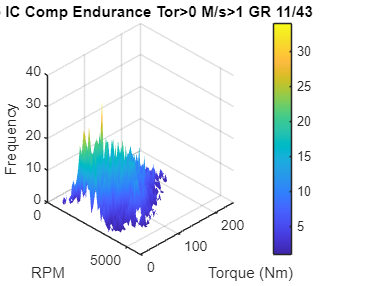

% --- Load input CSV ---
inputFile = "C:\Users\Tom Cruise\OneDrive - University of Victoria (1)\MENG FSAE - UVic FSAE SharePoint\DESIGN RESOURCES\Design Event Prep\Requirement Generation\Motor Eff\Motor Heat Gen\Emrax Efficency\Outputs\OnlyPosTorqueWasteful2025Endur.csv";
tbl = readtable(inputFile);

rpm = tbl.RPM;
torque = tbl.Torque;

% --- Bin size (adjust as needed) ---
rpm_bin_size = 100;      % RPM per bin
torque_bin_size = 5;     % Nm per bin

% --- Define bin edges ---
rpm_edges = min(rpm):rpm_bin_size:max(rpm);
torque_edges = min(torque):torque_bin_size:max(torque);

% --- Compute 2D histogram (frequency count) ---
[counts, ~, ~] = histcounts2(rpm, torque, rpm_edges, torque_edges);

% --- Compute bin centers for 3D surface plot ---
[rpm_grid, torque_grid] = meshgrid( ...
    rpm_edges(1:end-1) + rpm_bin_size/2, ...
    torque_edges(1:end-1) + torque_bin_size/2 ...
);

% --- Set 0-frequency bins to NaN (so they appear blank/white) ---
counts(counts == 0) = NaN;

% --- Plot 3D histogram as surface ---
figure;
surf(rpm_grid, torque_grid, counts', 'FaceColor', 'interp','EdgeColor','none');
xlabel('RPM');
ylabel('Torque (Nm)');
zlabel('Frequency');
title('2025 IC Comp Endurance Tor>0 M/s>1 GR 11/43');
view(45, 30);
colorbar;
grid on;
% --- Set axis limits (adjust values as needed) ---
xlim([0 5800]);   % Example RPM range
ylim([0 250]);       % Example Torque range